# Cointegration Exercise 

**Sinead Morrow : 23597852**

**Gaby Jacobs : **

**Abdul Cassiem : **

Objective: test for cointegration between the two interest rates (short term interest rates, e.g., CB policy rates or 3-month Government Treasury Bills) and determine how close to the predicted relationship the best model with cointegration yields. 

## Uncovered Interest Parity hypothesis

In international finance, the Fischer model predicts that the expected depreciation of a nominal exchange rate is a function of the interest rate differential. If the foreign interest rate increases relative to the domestic interest rate, we expect capital to flow out and the exchange rate to weaken (i.e. increase in our conventions: e = ZAR:USD).


$$E_t(e_{t+1})-e_t=i^{*}_t - i_t$$


Unfortunately, we don't have obvious measures of expected exchange rates (futures would have worked, but are hard to come by).

However, economic theory also suggest that expected depreciation$s_t=E_t(e_{t+1})-e_t$ should be stationary in equilibrium, unless there a non-stationary component to relative competitiveness of the two countries. 

At least we can do the following. If the two interest rates are each I(1), then we can test whether they are cointegrated as a minimum requirement for the theory. 

If the theory held exactly:


$$\left[\begin{array}{cc}
-1 & 1\end{array}\right]\left[\begin{array}{c}
i_{t}\\
i^{*}_{t}
\end{array}\right]=s_{t}\sim I(0)
\]$$


Again, in the real world, we expect deviations - there are many interest rates to choose from and the basic theory does not allow for a risk premium (which, if constant, would imply a constant in the cointegration relationship). 

## Import and visualize the data 

 clear
 load("cointegration_tutorial_data_2022.mat")
 

As always, we must be cognisant of the economic environtment we study with regards to the constancy of the data generating process. Before 1995, South Africa had a dual exchange rate system. After the GFC, the relationship and risk premia may have changed, so we restrict the sample for the first exercises.

Finally, numerical methods work best when data are similar in order of magnitude. Given that the level of a price index is meaningless, so we can rescale the two price series freely, so the simplest and clearest option is to let all variables start at the logarithmic value of the nominal exchange rate at the start of the sample

Create a logical vector with "True" in our sample and "False" elsewhere

sample = (dates>="01-Jan-1996"&dates<="01-Jun-2007");(dates>="01-Jan-1995");

Rebase the price series to start at the same value as the exchange rate at the beginning of the sample, we will not rebase the interest rate series since it has fundamental meaning in levels:

E_ZAR_USD = E_ZAR_USD(sample,:); 
P_USA = P_USA(sample,:);
P_USA = (P_USA/P_USA(1))*E_ZAR_USD(1);
P_RSA = P_RSA(sample,:);
P_RSA = (P_RSA/P_RSA(1))*E_ZAR_USD(1);
dates = dates(sample,:);
e = log(E_ZAR_USD);
p_star = log(P_USA);
p = log(P_RSA);
i = I_3m_RSA(sample);
i_star = I_3m_USA(sample);
ppp_data = [e,p_star,p];
uip_data = [i,i_star];

Plotting the PPP data

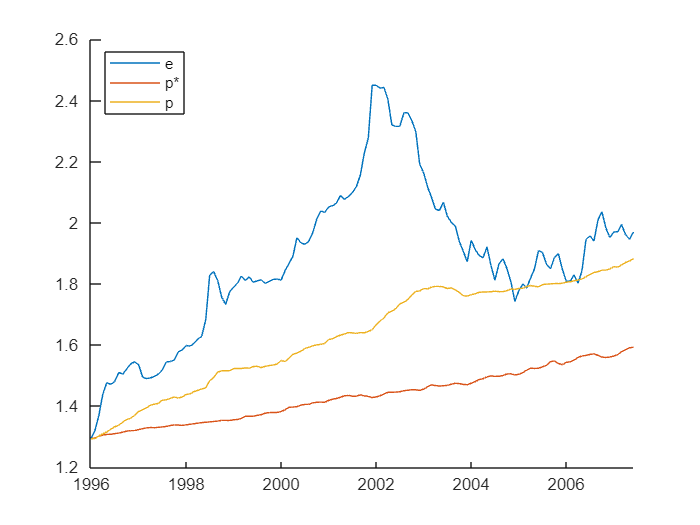

figure
hold on
plot(dates,ppp_data)
legend("e","p*","p",'Location',"best")

Plotting the UIP data

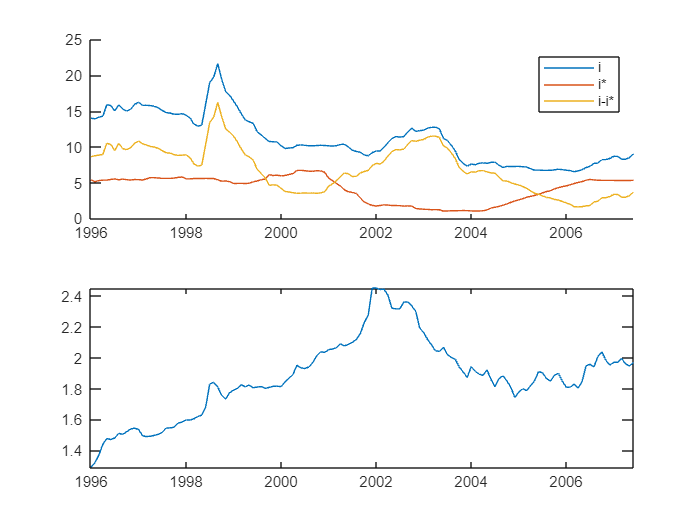

figure 
subplot(2,1,1)
hold on
plot(dates,i)
plot(dates,i_star)
plot(dates,i-i_star)
legend("i","i*","i-i*",'location',"best")
subplot(2,1,2)
plot(dates,e)

## 1. Formal unit root tests:

Augmented Dickey-Fuller test:

Since we have already done ADF tests for the PPP data in the tut, we have not replicated them again. 

It doesn't seem like there are any clear trends in the interest rate series, but the series might be deteriorating and would have a seasonality component so a cautious approach might want to allow for a trend. We conclude that the most logical test for the ADF test is that both series follow a unit root with drift against the alternatives that:

(i) interest rates are stationary around a deterministic trend

(ii) interest rates are stationary with drift

Using the test equation $\triangle y_t = a_0 + a_2 t +\gamma y_{t-1} +\sum_{i=2}^{p} \beta_i \triangle  y_{t-i+1}+ \varepsilon_t $,  we test the null $H_0: \gamma=a_2=0$, i.e. $y_t$ is a random walk with drift against the alternative $H_a: a_2 \neq 0, \gamma<0$, i.e.$y_t$ is a ARMA process around a deterministic trend)

We do the test for a range of lagged differences and use the BIC to choose the best model of the test.

**i**

against a trend stationary alternative: 

lags = [0:4]';
for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i,'model','TS','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end
i_adf_TS = table(lags,stat,cValue,pValue,reject,BIC)

i_adf_TS = 5×6 table
    lags     stat      cValue      pValue     reject     BIC  
    ____    _______    _______    ________    ______    ______

     0       -1.763    -3.4445     0.70544    false     266.29
     1      -3.0715    -3.4448     0.11797    false      233.9
     2      -3.1602    -3.4451    0.097273    false     237.25
     3      -3.1608    -3.4454    0.097181    false     241.25
     4      -2.2156    -3.4457     0.48463    false     233.47


against a stationary alternative with drift: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i,'model','ARD','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end

i_adf_ARD = table(lags,stat,cValue,pValue,reject,BIC)

i_adf_ARD = 5×6 table
    lags     stat      cValue     pValue     reject     BIC  
    ____    _______    _______    _______    ______    ______

     0      -1.1329    -2.8834    0.67747    false     263.25
     1      -1.7666    -2.8836    0.39933    false     235.23
     2      -1.8303    -2.8838    0.37136    false     238.97
     3      -1.8006    -2.8839    0.38436    false     243.14
     4      -1.7377    -2.8841    0.41194    false     231.09


**i***

against a trend stationary alternative: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_star,'model','TS','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end
i_star_adf_TS = table(lags,stat,cValue,pValue,reject,BIC)

i_star_adf_TS = 5×6 table
    lags      stat      cValue     pValue     reject      BIC  
    ____    ________    _______    _______    ______    _______

     0       0.35871    -3.4445     0.9985    false     -69.725
     1      -0.75117    -3.4448    0.96646    false     -120.94
     2       -1.0908    -3.4451    0.92586    false      -123.3
     3       -1.3533    -3.4454    0.86939    false     -119.08
     4       -1.7648    -3.4457    0.70435    false        -117


against a stationary alternative with drift: 

for lag = 1:5
    [reject(lag,1),pValue(lag,1),stat(lag,1),cValue(lag,1),reg] = adftest(i_star,'model','ARD','lags',lag-1);
    BIC(lag,1) = reg.BIC;
end

i_star_adf_ARD = table(lags,stat,cValue,pValue,reject,BIC)

i_star_adf_ARD = 5×6 table
    lags      stat      cValue     pValue     reject      BIC  
    ____    ________    _______    _______    ______    _______

     0      -0.59169    -2.8834    0.86724    false     -70.822
     1       -1.0441    -2.8836    0.71642    false     -125.74
     2       -1.3859    -2.8838    0.56636    false     -128.17
     3       -1.5888    -2.8839    0.47729    false     -124.02
     4       -1.8682    -2.8841     0.3547    false     -121.84


The ADF test results suggest that both interest rate series, i and i*, follow a unit root process. Therefore conclude that interest rates follow at least an I(1) process.

## 2. Estimate Unrestricted VAR and assess adequacy

Create an model structure for a VAR(2) with two variables. 

First, we consider the estimation without a trend as an example of how to detect problems.

num_variables = 2;
num_lags = 4;
uip_var_no_trend = varm(num_variables,num_lags);
uip_var_no_trend.Trend = 0; % This option means we are excluding a trend

% estimate the model using the data:
uip_var_no_trend_est = estimate(uip_var_no_trend,uip_data);

% summarize the results:
summarize(uip_var_no_trend_est)

 
   AR-Stationary 2-Dimensional VAR(4) Model
 
    Effective Sample Size: 134
    Number of Estimated Parameters: 18
    LogLikelihood: -30.9823
    AIC: 97.9647
    BIC: 150.126
 
                      Value       StandardError    TStatistic      PValue  
                   ___________    _____________    __________    __________

    Constant(1)        0.20451       0.17023          1.2014         0.2296
    Constant(2)       0.044149      0.043626           1.012        0.31154
    AR{1}(1,1)          1.4019      0.085569          16.383     2.5322e-60
    AR{1}(2,1)       -0.022681       0.02193         -1.0343        0.30102
    AR{1}(1,2)         0.41873       0.33214          1.2607        0.20742
    AR{1}(2,2)          1.4485

uip_var_no_trend_resid = infer(uip_var_no_trend_est,uip_data);

## 2.1 Assess congruency

Formal Ljung-Box tests:

Lags = [3,6,9,12]';

for i = 1:2
    [reject,pValue,stat,cValue] = lbqtest(uip_var_no_trend_resid(:,i),'Lags',Lags);
    var_uip_no_trend_res_lbqtest = table(Lags,stat,cValue,pValue,reject)
end

var_uip_no_trend_res_lbqtest = 4×5 table
    Lags     stat     cValue    pValue     reject
    ____    ______    ______    _______    ______

      3     1.4486    7.8147    0.69417    false 
      6     8.0059    12.592    0.23767    false 
      9     8.1013    16.919    0.52397    false 
     12     9.2421    21.026    0.68213    false 


var_uip_no_trend_res_lbqtest = 4×5 table
    Lags     stat     cValue    pValue     reject
    ____    ______    ______    _______    ______

      3     3.3278    7.8147    0.34379    false 
      6     4.7679    12.592    0.57391    false 
      9     12.166    16.919    0.20409    false 
     12      12.63    21.026    0.39649    false 


## 2.2 Assess stability

A simple eye-ball test (not valid statistically) is to see how long it takes the IRFs to return to zero. If it takes very long, we suspect one or more unit roots. (Note: here we don't care about identification, just stability

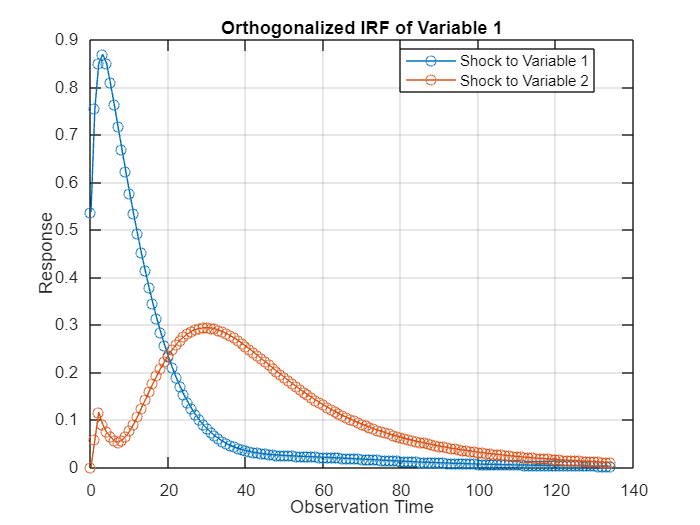

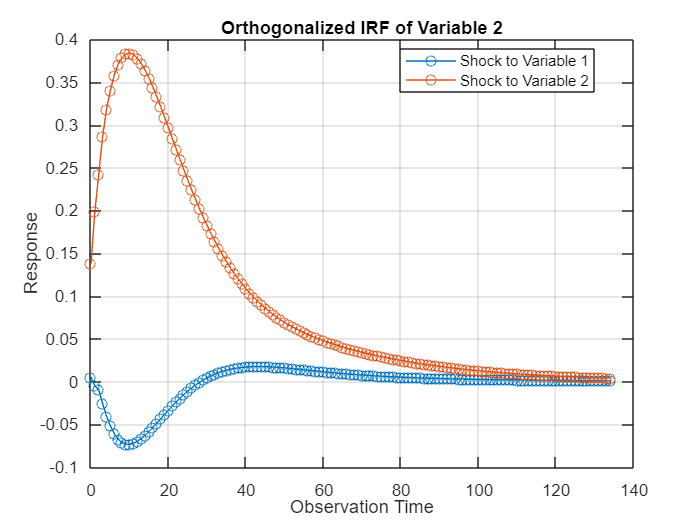

armairf(uip_var_no_trend_est.AR,[],"InnovCov",uip_var_no_trend_est.Covariance)

## Using the stability rule we derived for a VAR

companion_A = [uip_var_no_trend_est.AR{1},uip_var_no_trend_est.AR{2},uip_var_no_trend_est.AR{3};...
              eye(4),zeros(4,2)];
companion_matrix = VAR_companion(uip_var_no_trend_est.AR);
abs_characteristic_roots = abs(eig(companion_matrix))

abs_characteristic_roots =     0.3552
    0.4936
    0.4936
    0.4395
    0.4395
    0.9110
    0.9110
    0.9661


abs(eig(companion_A))

ans =     1.2185
    0.8371
    0.8371
    0.2285
    0.3172
    0.3172


max(abs_characteristic_roots)

ans = 0.9661

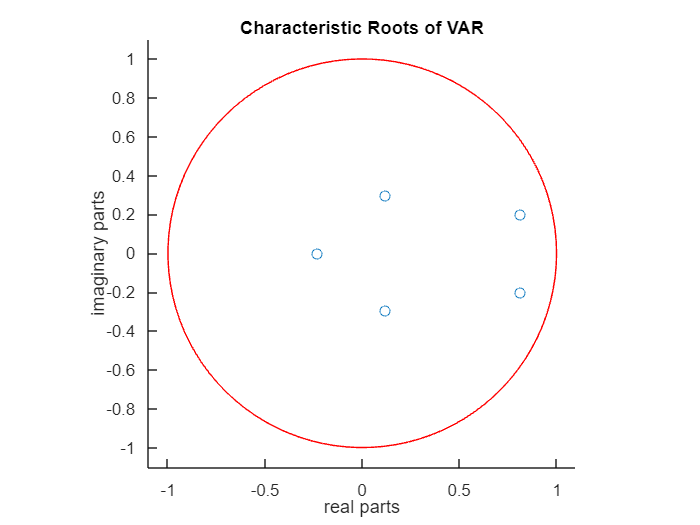

phi = linspace(0,2*pi,100)';
[x,y] = pol2cart(phi,ones(100,1));
        
figure
hold on
plot(eig(companion_A),'o')
plot(x,y,'r')
title('Characteristic Roots of VAR')
xlabel('real parts')
ylabel('imaginary parts')
axis([-1.1 1.1 -1.1 1.1])
axis square

The model without the trend is clearly not sufficient

adding a trend 